# **MATLAB Kursu**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com*

## DERS - 5

### 2-Boyutlu Grafik Çizdirme

MATLAB'de gerçekleştirilen neredeyse tüm projelerde, elde edilen sonuçları görmek için grafikler oluşturulur. Örneğin

- Matematiksel fonksiyonları,

- Rastlantı değişkenlerinin olasılık yoğunluk fonksiyonlarını,

- Bir sensörden toplanan verilerin nasıl dağıldığını,

- Herhangi bir değişkenin başka bir değişkene göre nasıl değiştiğini,

ve daha birçok merak edileni gözlemlemek için grafikler oldukça sık kullanılırlar. MATLAB'de grafik çizdirmek için kulanılan en temel fonksiyon `plot` fonksiyonudur. Örneğin bir sinüs fonksiyonu aşağıdaki gibi çizdirilebilir.

theta = 0 : 0.5 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);

Grafiğin arka planını ızgara biçiminde yapmak grafiği ve verileri gözlemlemeyi kolaylaştırır. Bunun için `grid` fonksiyonu kullanılabilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
grid;

Eksenlerin değer aralıklarını iyi ayarlamak gerekir, yoksa veriler doğru gözlemlenemez. Örneğin sinüs fonksiyonunun -1 ile 1 arasında dağıldığı bilinmektedir ve eğer sinüs fonksiyonu -1000 ile 1000 arasındaki değerlerde incelenirse, sanki açıdan bağımsız olarak sabit kalan ve 0 olan bir fonksiyonmuş zannedilebilir. Eksenlerin değiştiği değer aralıkları farklı şekillerde ayarlanabilir. Bunun için ilk olarak `axis` fonksiyonu kullanılabilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
axis([0 2 * pi -1000 1000]);
grid;

Eksen aralıkları aynı zamanda `xlim` ve `ylim` fonksiyonları kullanılarak da ayarlanabilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Eksenleri isimlendirmek elde edilen grafiği anlamlandırmak adına oldukça önemlidir. Burada x-ekseninin hangi değişkeni temsil ettiğini göstermek için `xlabel` fonksiyonu kullanılırken, y-ekseninin hangi değişkeni temsil ettiğini göstermek için de `ylabel` fonksiyonu kullanılır. Grafiğe başlık koyabilmek için de `title` fonksiyonu kullanılır.

Yunan alfabesi değişken tanımlamalarında sıkça kullanıldığı için grafiklere eklenmesi gerekebilir. Hangi harfin nasıl yazılacağı MathWorks sitesinde detaylı bir tablo olarak verilmiştir:

- Yunan Alfabesi: [https://www.mathworks.com/help/matlab/creating_plots/greek-letters-and-special-characters-in-graph-text.html](https://www.mathworks.com/help/matlab/creating_plots/greek-letters-and-special-characters-in-graph-text.html)

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
title("Sinüs Dalgası");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Eksenlerde çoklu satırlar oluşturulabilir. Örneğin x-ekseninde hem değişken hem de figür için ekstra bilgi aşağıdaki gibi eklenebilir:

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
title("Sinüs Dalgası");
xlabel(["\theta (rad)","(a)"]);
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Eksenlerdeki yazıların boyutları, tipleri ve renkleri de isteğe göre değiştirilebilir. Bunun için de kod aşağıdaki gibi düzenlenebilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave);
title("Sinüs Dalgası");
xlabel(["\theta (rad)","(a)"], "FontSize", 10, "FontWeight", "bold", "Color", "r");
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

MATLAB'de bazı harfler hazır olarak bazı renkler için tanımlanmıştır:

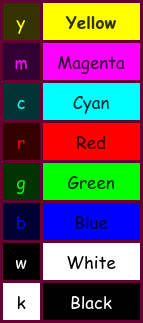              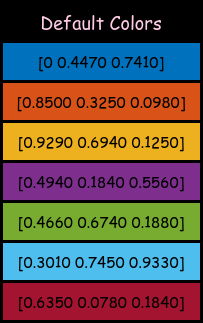

Ancak bunlar haricinde de RGB renk kodları ile istenen renk elde edilebilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave, "Color", [0.8500 0.3250 0.0980]);
title("Sinüs Dalgası");
xlabel(["\theta (rad)","(a)"]);
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Grafiğin kalınlığı da isteğe göre ayarlanabilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave, "Color", [0.8500 0.3250 0.0980],...
                       "LineWidth", 3);
title("Sinüs Dalgası");
xlabel(["\theta (rad)","(a)"]);
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Grafik sadece düz çizgi şeklinde olmak zorunda değildir, isteğe göre değiştirilebilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave, "v-.",...
                       "Color", [0.8500 0.3250 0.0980],...
                       "LineWidth", 2);
title("Sinüs Dalgası");
xlabel(["\theta (rad)","(a)"]);
ylabel("Fonksiyon");
xlim([1.4 1.5]);
ylim([-2 2]);
grid;

Grafiğin kalınlığı ve rengi değiştirilmeden sadece verilerin gösterildiği şekillerin kalınlığı ve rengi de değiştirilebilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
plot(theta, sine_wave, "o--",...
                       "Color", [0.8500 0.3250 0.0980],...
                       "LineWidth", 2,...
                       "MarkerEdgeColor", [0.8500 0.3250 0.0980], ...
                       "MarkerFaceColor", [0.9290 0.6940 0.1250], ...
                       "MarkerSize", 12);
title("Sinüs Dalgası");
xlabel(["\theta (rad)","(a)"]);
ylabel("Fonksiyon");
xlim([1.4 1.5]);
ylim([-2 2]);
grid;

Birden fazla veri aynı grafik üzerinde gözlemlenebilir. Bunun için `hold on` fonksiyonu kullanılabilir. Tüm çizim kodları tamamlandıktan sonra da `hold off` fonksiyonu ile çizimin bittiği bildirilmelidir ki sonraki çizimler de bu grafik üzerinde çıkmasın. Örneğin bir sinüs ve bir kosinüs fonksiyonu aynı grafik üzerinde aşağıdaki gibi gösterilebilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
cos_wave = cos(theta);

plot(theta, sine_wave);
hold on;
plot(theta, cos_wave);
hold off;

title("Sinüs ve Kosinüs Dalgaları");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Birden fazla veri aynı grafik üzerinde gösterilirken karışıklık olmaması açısından verileri tanımlamak gerekir. Bunun için de `legend` fonksiyonu kullanılır.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
cos_wave = cos(theta);

plot(theta, sine_wave);
hold on;
plot(theta, cos_wave);
hold off;

title("Sinüs ve Kosinüs Dalgaları");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
legend("Sinüs","Kosinüs");
xlim([0 2 * pi]);
ylim([-2 2]);
grid;

Birden fazla veriyi ayrık grafiklerde ancak tek bir figür olarak göstermek için `subplot` fonksiyonu kullanılabilir.

theta = 0 : 0.01 : 2 * pi;
sine_wave = sin(theta);
cos_wave = cos(theta);

x = -10 : 10;
square_x = x.^2;
cube_x = x.^3;

subplot(2, 2, 1);
plot(theta, sine_wave, "LineWidth", 2,...
                       "Color", [0.9290 0.6940 0.1250]);
title("Sinüs");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
grid;

subplot(2, 2, 2);
plot(theta, cos_wave, "LineWidth", 2,...
                      "Color", [0 0.4470 0.7410]);
title("Kosinüs");
xlabel("\theta (rad)");
ylabel("Fonksiyon");
grid;

subplot(2, 2, 3);
plot(x, square_x, "--",...  
                  "LineWidth", 2,...
                  "Color", [0.4660 0.6740 0.1880]);
title("x^{2}");
xlabel("x");
ylabel("Fonksiyon");
grid;

subplot(2, 2, 4);
plot(x, cube_x, "-.",...  
                "LineWidth", 2,...
                "Color", [0.4940 0.1840 0.5560]);
title("x^{3}");
xlabel("x");
ylabel("Fonksiyon");
grid;

 

MATLAB Live Script kapsamında yazılan programlara interaktif kontroller eklenebilir. Bunun için **LIVE EDITOR **sekmesinde **Control **kısmından istenen interaktif kontrol eklenebilir. Örneğin Gibbs teoremi interaktif bir slider ile çalıştırılabilir. Gibbs teoremine göre çok sayıda sinüs fonksiyonu aşağıda verilen formatta toplanırsa kare fonksiyon elde edilebilir:


$$\text{square}(x,n) = \text{sin}(x) + \frac{1}{3}\text{sin}(3x) + \frac{1}{5}\text{sin}(5x) + \dots + \frac{1}{n}\text{sin}(nx)$$
 

İnteraktif slider sayesinde değişen $n$ değerleri için sinüs fonksiyonlarının kare fonksiyona ne kadar yaklaştığı dinamik olarak gözlemlenebilir.

n = 1;
x = 0 : 1e-5 : 2 * pi;
square_wave = SquareWave(x, n);
plot(x, square_wave, "-",...
                     "LineWidth", 1.5,...
                     "Color", [0.6350 0.0780 0.1840]);
title_string = strcat(string(n), ". Degree Sum");
title(title_string);
xlabel("x");
ylabel("Sum of Sine Waves");
grid;

Plot komutuna alternatif olarak başka çizdirme fonksiyonları da vardır. Eğer y-ekseni logaritmik olarak çizdirilmek istenirse `semilogy` fonksiyonu kullanılabilir.

x = [1e-6 1e-5 1e-4 1e-3 1e-2 1e-1 1 1e1 1e2 1e3 1e4 1e5];

figure;
subplot(1, 2, 1);
plot(x, "-o", "LineWidth", 1.5,...
              "Color", [0.8500 0.3250 0.0980],...
              "MarkerSize", 8,...
              "MarkerFaceColor", [0.8500 0.3250 0.0980]);
title("PLOT");
grid;

subplot(1, 2, 2);
semilogy(x, "-o", "LineWidth", 1.5,...
                  "Color", [0.3010 0.7450 0.9330],...
                  "MarkerSize", 8,...
                  "MarkerFaceColor", [0.3010 0.7450 0.9330]);
title("SEMILOGY");
grid;

Ayrık fonksiyonları göstermek için `stem` fonksiyonu kullanılabilir.

figure;
daily_temperatures = [-1 4 5 6 5 2];
days = [1 2 3 4 5 6];
stem(days, daily_temperatures);
xlabel("Days");
ylabel("Temperature");
grid;

Histogram çizdirmek için `histogram` fonksiyonu kullanılabilir. Histogram, bir vektörü eşit aralıklara böler ve her bir aralıkta kaçar tane eleman olduğunu gösterir. Aslında vektörün dağılımını verir.

% Uniform distribution between 0 and 1.
uni_vec = rand(1, 1e5);
histogram(uni_vec);
grid;

% Uniform distribution of integers between 1 and 5
uni_int_vec = randi([1, 5], [1, 1e5]);
h1 = histogram(uni_int_vec);
h1.Normalization = "pdf";
grid;

% Gaussian distribution with means -4, -2, 2, and 4
gaussian_vec = randn(1, 1e5) - 4;
h2 = histogram(gaussian_vec);
h2.Normalization = "pdf";
hold on;

gaussian_vec = randn(1, 1e5) - 2;
h3 = histogram(gaussian_vec);
h3.Normalization = "pdf";
hold on;

gaussian_vec = randn(1, 1e5) + 2;
h4 = histogram(gaussian_vec);
h4.Normalization = "pdf";
hold on;

gaussian_vec = randn(1, 1e5) + 4;
h5 = histogram(gaussian_vec);
h5.Normalization = "pdf";
grid;

% Exponential distribution with lambda 0.8, 1, and 1.2
x = 0 : 5e-5 : 5;

lambda = 0.8;
exponential_vec = lambda * exp(-lambda * x);
h6 = histogram(exponential_vec);
h6.Normalization = "pdf";
hold on;

lambda = 1;
exponential_vec = -lambda * exp(-lambda * x);
h7 = histogram(exponential_vec);
h7.Normalization = "pdf";
hold on;

lambda = 1.2;
exponential_vec = lambda * exp(-lambda * x);
h8 = histogram(exponential_vec);
h8.Normalization = "pdf";
grid;

### 3-Boyutlu Grafik Çizdirme

İki değişkene bağlı olan fonksiyonların grafiklerini incelemek ve bazı üç boyutlu modellemeleri gerçekleştirmek için üç boyutlu grafikler gerekmektedir. Üç boyutlu grafikleri elde etmek için öncelikle `meshgrid` fonksiyonu kullanılmalıdır. Bu fonksiyon iki adet matris oluşturur:

- Her satırında $x$ vektörünü (birinci bağımsız değişken) içeren bir **X **matrisi

- Her sütununda $y$ vektörünü (ikinci bağımsız değişken) içeren bir **Y** matrisi

Sonra bu matrisler kullanılarak $x$ ve $y$ değişkenlerine bağlı olan bağımsız değişken `surf` fonksiyonu ile çizdirilir. Örneğin $f(x,y) = xe^{-x^{2}-y^{2}}$ fonksiyonu, $x \in [-2, 2]$ ve $y \in [-4, 4]$ aralıkları için üç boyutlu olarak aşağıdaki gibi çizdirilebilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surf(X, Y, Z);
xlabel("x");
ylabel("y");
zlabel("z");

Üç boyutlu çizim haritadaki farklı değerler için farklı renkler almaktadır. Bu renk skalası `colormap` fonksiyonu kullanılarak değiştirilebilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surf(X, Y, Z);
colormap(prism);
xlabel("x");
ylabel("y");
zlabel("z");

Benzer bir biçimde `mesh` fonksiyonu kullanılarak da aynı grafik yüzeyler boş kalacak şekilde elde edilebilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
mesh(X, Y, Z);
xlabel("x");
ylabel("y");
zlabel("z");

İzohips benzeri bir grafik elde edebilmek için `contour` fonksiyonu kullanılabilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
contour(X, Y, Z, 10);
xlabel("x");
ylabel("y");
zlabel("z");

Son olarak da hem üç boyutlu grafiği hem de izdüşümünü görmek için `surfc` fonksiyonu kullanılabilir.

x = -2 : 0.15 : 2;
y = -4 : 0.15 : 4;

[X, Y] = meshgrid(x, y);
Z = X .* exp(-X.^2 - Y.^2);
surfc(X, Y, Z);
colormap(lines)
xlabel("x");
ylabel("y");
zlabel("z");